clear all
figure

data = readtable("Optimisation4.xlsx")

data = 50×16 table
    GradTime    InitalOM    FinalOM    Temp    IsoHoldTime    InjVol    FlowRate    Column    OMPhase    Ph     RsCrit2     Maximisepeaknumber    Minimisemethodtime    CombinedFunction1    WeightRespcmtmdHPLC018     Dist2  
    ________    ________    _______    ____    ___________    ______    ________    ______    _______    __    _________    __________________    __________________    _________________    ______________________    _______


resultTab = data{:, :};
resultTab = resultTab(:,[11,12,13])

resultTab =    -1.7583   -1.7918    2.0499
   -2.0369   -1.7918    2.6449
    0.4446   -1.9459    2.0469
   -0.7768   -1.9459    1.9696
   -0.2340   -1.7918    0.8529
   -0.6510   -1.9459    2.3556
    0.0072   -1.9459    2.5100
   -0.5022   -1.9459    2.4904
   -0.3481   -1.7918    1.2538
    0.1621   -1.9459    1.4706



resultTab(:,1) = exp(-resultTab(:,1))

resultTab =     5.8027   -1.7918    2.0499
    7.6671   -1.7918    2.6449
    0.6411   -1.9459    2.0469
    2.1745   -1.9459    1.9696
    1.2637   -1.7918    0.8529
    1.9174   -1.9459    2.3556
    0.9928   -1.9459    2.5100
    1.6523   -1.9459    2.4904
    1.4164   -1.7918    1.2538
    0.8504   -1.9459    1.4706


resultTab(:,2) = exp(-resultTab(:,2))

resultTab =     5.8027    6.0000    2.0499
    7.6671    6.0000    2.6449
    0.6411    7.0000    2.0469
    2.1745    7.0000    1.9696
    1.2637    6.0000    0.8529
    1.9174    7.0000    2.3556
    0.9928    7.0000    2.5100
    1.6523    7.0000    2.4904
    1.4164    6.0000    1.2538
    0.8504    7.0000    1.4706


resultTab(:,3) = -exp(resultTab(:,3))

resultTab =     5.8027    6.0000   -7.7670
    7.6671    6.0000  -14.0825
    0.6411    7.0000   -7.7436
    2.1745    7.0000   -7.1678
    1.2637    6.0000   -2.3463
    1.9174    7.0000  -10.5446
    0.9928    7.0000  -12.3049
    1.6523    7.0000  -12.0657
    1.4164    6.0000   -3.5037
    0.8504    7.0000   -4.3517



utopiaPoint1 = [max(resultTab(:,1)), max(resultTab(:,2)), max(resultTab(:,3))]

utopiaPoint1 =     7.6671    7.0000   -1.9937


antiutopiaPointTemp = [min(resultTab(:,1)), min(resultTab(:,2)), min(resultTab(:,3))]

antiutopiaPointTemp =     0.2623    6.0000  -14.0825



antiutopiaPointCorr = 0.01.*(utopiaPoint1-antiutopiaPointTemp)

antiutopiaPointCorr =     0.0740    0.0100    0.1209


antiutopiaPoint1 = antiutopiaPointTemp - antiutopiaPointCorr 

antiutopiaPoint1 =     0.1882    5.9900  -14.2034



data = readtable("Optimisation5.xlsx")

data = 50×16 table
    GradTime    InitalOM    FinalOM    Temp    IsoHoldTime    InjVol    FlowRate    Column    OMPhase    Ph     RsCrit2     Maximisepeaknumber    Minimisemethodtime    CombinedFunction1    WeightRespcmtmdHPLC018     Dist2  
    ________    ________    _______    ____    ___________    ______    ________    ______    _______    __    _________    __________________    __________________    _________________    ______________________    _______


resultTab = data{:, :};
resultTab = resultTab(:,[11,12,13])

resultTab =    -0.6970   -1.9459    1.6285
    0.4371   -1.9459    2.5872
    0.4105   -1.9459    1.4989
    0.0070   -1.9459    2.4750
   -0.5102   -1.9459    2.5233
   -1.2863   -1.7918    2.1888
   -0.3084   -1.7918    1.3098
    0.0636   -1.9459    1.5350
   -0.2144   -1.9459    2.0855
   -0.1888   -1.7918    1.0532



resultTab(:,1) = exp(-resultTab(:,1))

resultTab =     2.0076   -1.9459    1.6285
    0.6459   -1.9459    2.5872
    0.6633   -1.9459    1.4989
    0.9931   -1.9459    2.4750
    1.6656   -1.9459    2.5233
    3.6192   -1.7918    2.1888
    1.3612   -1.7918    1.3098
    0.9384   -1.9459    1.5350
    1.2391   -1.9459    2.0855
    1.2078   -1.7918    1.0532


resultTab(:,2) = exp(-resultTab(:,2))

resultTab =     2.0076    7.0000    1.6285
    0.6459    7.0000    2.5872
    0.6633    7.0000    1.4989
    0.9931    7.0000    2.4750
    1.6656    7.0000    2.5233
    3.6192    6.0000    2.1888
    1.3612    6.0000    1.3098
    0.9384    7.0000    1.5350
    1.2391    7.0000    2.0855
    1.2078    6.0000    1.0532


resultTab(:,3) = -exp(resultTab(:,3))

resultTab =     2.0076    7.0000   -5.0962
    0.6459    7.0000  -13.2921
    0.6633    7.0000   -4.4767
    0.9931    7.0000  -11.8814
    1.6656    7.0000  -12.4696
    3.6192    6.0000   -8.9247
    1.3612    6.0000   -3.7056
    0.9384    7.0000   -4.6412
    1.2391    7.0000   -8.0488
    1.2078    6.0000   -2.8669



utopiaPoint2 = [max(resultTab(:,1)), max(resultTab(:,2)), max(resultTab(:,3))]

utopiaPoint2 =     3.6192    7.0000   -2.0399


antiutopiaPointTemp = [min(resultTab(:,1)), min(resultTab(:,2)), min(resultTab(:,3))]

antiutopiaPointTemp =     0.5779    6.0000  -13.2921



antiutopiaPointCorr = 0.01.*(utopiaPoint2-antiutopiaPointTemp)

antiutopiaPointCorr =     0.0304    0.0100    0.1125


antiutopiaPoint2 = antiutopiaPointTemp - antiutopiaPointCorr 

antiutopiaPoint2 =     0.5475    5.9900  -13.4047



data = readtable("Optimisation6.xlsx")

data = 50×16 table
    GradTime    InitalOM    FinalOM    Temp    IsoHoldTime    InjVol    FlowRate    Column    OMPhase    Ph    RsCrit2     Maximisepeaknumber    Minimisemethodtime    CombinedFunction1    WeightRespcmtmdHPLC018     Dist2  
    ________    ________    _______    ____    ___________    ______    ________    ______    _______    __    ________    __________________    __________________    _________________    ______________________    ________<


resultTab = data{:, :};
resultTab = resultTab(:,[11,12,13])

resultTab =     0.3071   -1.9459    1.9270
   -0.4678   -1.9459    1.8442
   -0.7088   -1.9459    2.1860
    0.3579   -1.9459    1.9763
    0.8509   -1.9459    2.4039
   -0.4438   -1.9459    2.4387
   -0.2431   -1.7918    1.1727
   -0.7107   -1.9459    2.0382
   -0.6842   -1.9459    2.4257
   -0.5082   -1.9459    1.5379



resultTab(:,1) = exp(-resultTab(:,1))

resultTab =     0.7356   -1.9459    1.9270
    1.5965   -1.9459    1.8442
    2.0316   -1.9459    2.1860
    0.6991   -1.9459    1.9763
    0.4270   -1.9459    2.4039
    1.5586   -1.9459    2.4387
    1.2751   -1.7918    1.1727
    2.0353   -1.9459    2.0382
    1.9823   -1.9459    2.4257
    1.6622   -1.9459    1.5379


resultTab(:,2) = exp(-resultTab(:,2))

resultTab =     0.7356    7.0000    1.9270
    1.5965    7.0000    1.8442
    2.0316    7.0000    2.1860
    0.6991    7.0000    1.9763
    0.4270    7.0000    2.4039
    1.5586    7.0000    2.4387
    1.2751    6.0000    1.1727
    2.0353    7.0000    2.0382
    1.9823    7.0000    2.4257
    1.6622    7.0000    1.5379


resultTab(:,3) = -exp(resultTab(:,3))

resultTab =     0.7356    7.0000   -6.8686
    1.5965    7.0000   -6.3227
    2.0316    7.0000   -8.8994
    0.6991    7.0000   -7.2157
    0.4270    7.0000  -11.0665
    1.5586    7.0000  -11.4580
    1.2751    6.0000   -3.2308
    2.0353    7.0000   -7.6771
    1.9823    7.0000  -11.3097
    1.6622    7.0000   -4.6548



utopiaPoint3 = [max(resultTab(:,1)), max(resultTab(:,2)), max(resultTab(:,3))]

utopiaPoint3 =     2.1073    7.0000   -1.9204


antiutopiaPointTemp = [min(resultTab(:,1)), min(resultTab(:,2)), min(resultTab(:,3))]

antiutopiaPointTemp =     0.3944    6.0000  -14.3853



antiutopiaPointCorr = 0.01.*(utopiaPoint3-antiutopiaPointTemp)

antiutopiaPointCorr =     0.0171    0.0100    0.1246


antiutopiaPoint3 = antiutopiaPointTemp - antiutopiaPointCorr

antiutopiaPoint3 =     0.3773    5.9900  -14.5099




utopiaPoint = max([utopiaPoint1; utopiaPoint2; utopiaPoint3])

utopiaPoint =     7.6671    7.0000   -1.9204


antiutopiaPoint = min([antiutopiaPoint1;antiutopiaPoint2;antiutopiaPoint3])

antiutopiaPoint =     0.1882    5.9900  -14.5099


%Optimisation 4
figure

load("Optimisation4.mat")

dataTab = data{2, 2};
dataTab = dataTab{:,[1,2,5]}

dataTab =     4.4400   12.9400    3.2200
    7.8500    8.8200    7.3900
    9.4400   45.1900    4.5900
    6.3600   31.8100    2.4000
    1.3000   58.7800    0.6700
    3.3600   27.0000    7.0100
    5.0300   41.0900    9.8400
    9.5577   24.7128    5.4951
    1.4658   53.8898    1.8158
    1.6965   19.9607    1.7275



resultTab = data{3, 2};
resultTab = resultTab{:,[1,2,3]};
resultTab = cell2mat(resultTab)

resultTab =    -1.7583   -1.7918    2.0499
   -2.0369   -1.7918    2.6449
    0.4446   -1.9459    2.0469
   -0.7768   -1.9459    1.9696
   -0.2340   -1.7918    0.8529
   -0.6510   -1.9459    2.3556
    0.0072   -1.9459    2.5100
   -0.5022   -1.9459    2.4904
   -0.3481   -1.7918    1.2538
    0.1621   -1.9459    1.4706



resultTab(:,1) = exp(-resultTab(:,1))

resultTab =     5.8027   -1.7918    2.0499
    7.6671   -1.7918    2.6449
    0.6411   -1.9459    2.0469
    2.1745   -1.9459    1.9696
    1.2637   -1.7918    0.8529
    1.9174   -1.9459    2.3556
    0.9928   -1.9459    2.5100
    1.6523   -1.9459    2.4904
    1.4164   -1.7918    1.2538
    0.8504   -1.9459    1.4706


resultTab(:,2) = exp(-resultTab(:,2))

resultTab =     5.8027    6.0000    2.0499
    7.6671    6.0000    2.6449
    0.6411    7.0000    2.0469
    2.1745    7.0000    1.9696
    1.2637    6.0000    0.8529
    1.9174    7.0000    2.3556
    0.9928    7.0000    2.5100
    1.6523    7.0000    2.4904
    1.4164    6.0000    1.2538
    0.8504    7.0000    1.4706


resultTab(:,3) = -exp(resultTab(:,3))

resultTab =     5.8027    6.0000   -7.7670
    7.6671    6.0000  -14.0825
    0.6411    7.0000   -7.7436
    2.1745    7.0000   -7.1678
    1.2637    6.0000   -2.3463
    1.9174    7.0000  -10.5446
    0.9928    7.0000  -12.3049
    1.6523    7.0000  -12.0657
    1.4164    6.0000   -3.5037
    0.8504    7.0000   -4.3517



paretoF = paretoFront([resultTab(:,1) resultTab(:,2) resultTab(:,3)])

paretoF =     5.8027    6.0000   -7.7670
    7.6671    6.0000  -14.0825
    2.1945    7.0000   -2.7993
    1.4644    7.0000   -2.0401
    2.2006    7.0000   -3.0029
    1.0379    7.0000   -1.9937


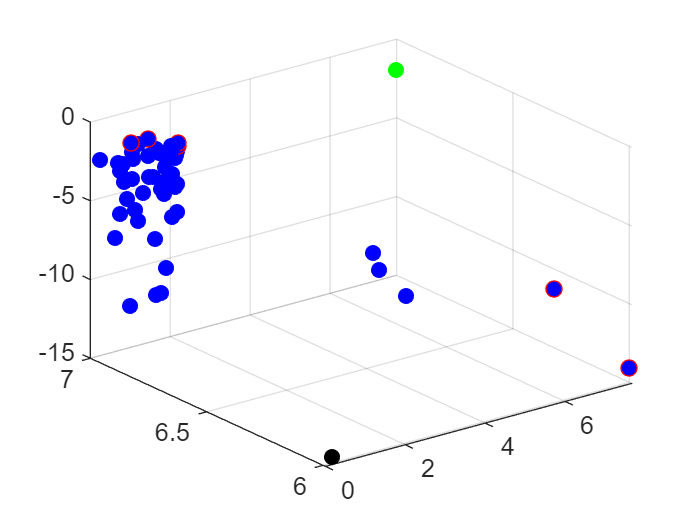


scatter3(resultTab(:,1), resultTab(:,2), resultTab(:,3), "bo", "filled")

hold on
scatter3(paretoF(:,1), paretoF(:,2), paretoF(:,3), "ro")
scatter3(utopiaPoint(1), utopiaPoint(2), utopiaPoint(3), "go", "filled")
scatter3(antiutopiaPoint(1), antiutopiaPoint(2), antiutopiaPoint(3), "ko", "filled")
hold off


allHV = [];
for x = 7:length(resultTab(:,1))

    paretoF = paretoFront([resultTab(1:x,1) resultTab(1:x,2) resultTab(1:x,3)]);
    allHV = [allHV; hypervolume([paretoF(:,1), paretoF(:,2), paretoF(:,3)], antiutopiaPoint, utopiaPoint, 1000000)];

end

allMinHV = minResp(-allHV)

allMinHV =    -0.1575
   -0.1584
   -0.1584
   -0.1781
   -0.2233
   -0.2237
   -0.2237
   -0.2237
   -0.2237
   -0.2250


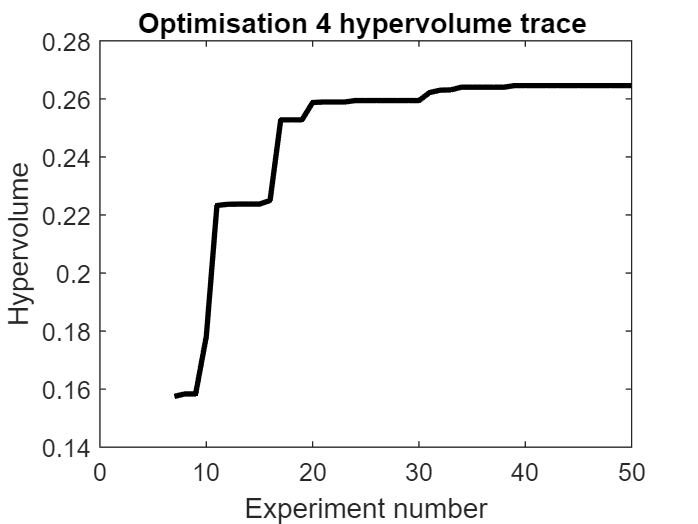


plot(7:50, -allMinHV, "black", "LineWidth", 2)

xlabel("Experiment number")
ylabel("Hypervolume")

title("Optimisation 4 hypervolume trace ")

%Optimisation 5
figure

load("Optimisation5.mat")

dataTab = data{2, 2};
dataTab = dataTab{:,[1,2,5]}

dataTab =     6.1400   31.3200    0.3000
    9.6800    7.8100    5.5100
    2.5800   45.1300    1.9200
    8.1800   41.0200    8.6500
    4.7300   25.5700    8.1600
    1.7400   14.9300    6.2300
    6.0100   56.3200    4.0900
    2.4410   41.7019    1.9717
    2.7931   22.6389    4.7213
    8.5667   60.0000    6.9877



resultTab = data{3, 2};
resultTab = resultTab{:,[1,2,3]};
resultTab = cell2mat(resultTab)

resultTab =    -0.6970   -1.9459    1.6285
    0.4371   -1.9459    2.5872
    0.4105   -1.9459    1.4989
    0.0070   -1.9459    2.4750
   -0.5102   -1.9459    2.5233
   -1.2863   -1.7918    2.1888
   -0.3084   -1.7918    1.3098
    0.0636   -1.9459    1.5350
   -0.2144   -1.9459    2.0855
   -0.1888   -1.7918    1.0532



resultTab(:,1) = exp(-resultTab(:,1))

resultTab =     2.0076   -1.9459    1.6285
    0.6459   -1.9459    2.5872
    0.6633   -1.9459    1.4989
    0.9931   -1.9459    2.4750
    1.6656   -1.9459    2.5233
    3.6192   -1.7918    2.1888
    1.3612   -1.7918    1.3098
    0.9384   -1.9459    1.5350
    1.2391   -1.9459    2.0855
    1.2078   -1.7918    1.0532


resultTab(:,2) = exp(-resultTab(:,2))

resultTab =     2.0076    7.0000    1.6285
    0.6459    7.0000    2.5872
    0.6633    7.0000    1.4989
    0.9931    7.0000    2.4750
    1.6656    7.0000    2.5233
    3.6192    6.0000    2.1888
    1.3612    6.0000    1.3098
    0.9384    7.0000    1.5350
    1.2391    7.0000    2.0855
    1.2078    6.0000    1.0532


resultTab(:,3) = -exp(resultTab(:,3))

resultTab =     2.0076    7.0000   -5.0962
    0.6459    7.0000  -13.2921
    0.6633    7.0000   -4.4767
    0.9931    7.0000  -11.8814
    1.6656    7.0000  -12.4696
    3.6192    6.0000   -8.9247
    1.3612    6.0000   -3.7056
    0.9384    7.0000   -4.6412
    1.2391    7.0000   -8.0488
    1.2078    6.0000   -2.8669



paretoF = paretoFront([resultTab(:,1) resultTab(:,2) resultTab(:,3)])

paretoF =     3.6192    6.0000   -8.9247
    1.4948    7.0000   -2.2675
    1.4788    7.0000   -2.0399
    1.9980    7.0000   -2.6785
    2.0493    7.0000   -4.5528
    2.0266    7.0000   -3.5349
    2.0313    7.0000   -4.0774


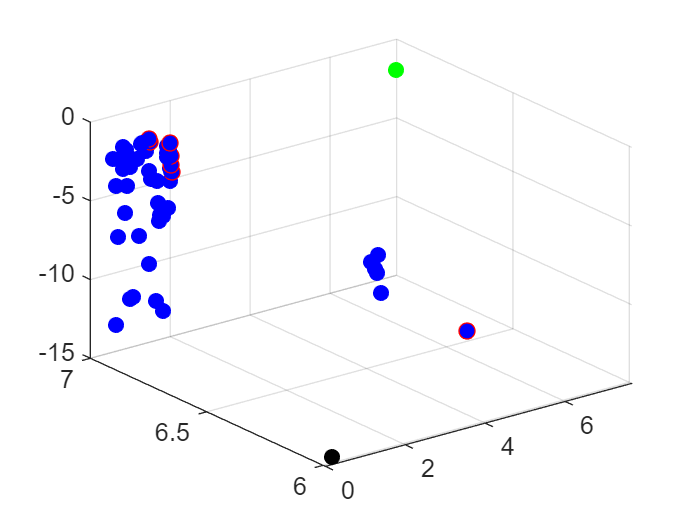

hv = 0.2427


scatter3(resultTab(:,1), resultTab(:,2), resultTab(:,3), "bo", "filled")

hold on
scatter3(paretoF(:,1), paretoF(:,2), paretoF(:,3), "ro")
scatter3(utopiaPoint(1), utopiaPoint(2), utopiaPoint(3), "go", "filled")
scatter3(antiutopiaPoint(1), antiutopiaPoint(2), antiutopiaPoint(3), "ko", "filled")
hold off

allHV = [];
for x = 7:length(resultTab(:,1))

    paretoF = paretoFront([resultTab(1:x,1) resultTab(1:x,2) resultTab(1:x,3)]);
    allHV = [allHV; hypervolume([paretoF(:,1), paretoF(:,2), paretoF(:,3)], antiutopiaPoint, utopiaPoint, 1000000)];

end

allMinHV = minResp(-allHV)

allMinHV =    -0.1865
   -0.1872
   -0.1876
   -0.1877
   -0.1933
   -0.2121
   -0.2121
   -0.2297
   -0.2333
   -0.2333


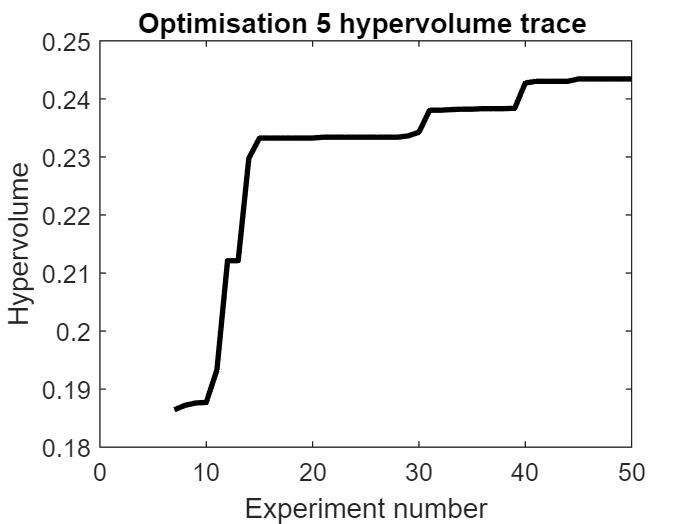


plot(7:50, -allMinHV, "black", "LineWidth", 2)

xlabel("Experiment number")
ylabel("Hypervolume")

title("Optimisation 5 hypervolume trace ")

%Optimisation 6
figure

load("Optimisation6.mat")

dataTab = data{2, 2};
dataTab = dataTab{:,[1,2,5]}

dataTab =     8.2400   11.5200    0.0500
    4.7400   24.9400    1.9200
    8.9600   29.8700    2.9800
    2.9100   44.4200    4.8500
    5.4400   13.4100    5.9200
    1.4700   36.4800    9.3400
    7.2700   58.0900    7.4500
    3.0565   30.6136    4.3821
    2.0991   29.1360    8.5705
    4.5406   27.0935    0.4237



resultTab = data{3, 2};
resultTab = resultTab{:,[1,2,3]};
resultTab = cell2mat(resultTab)

resultTab =     0.3071   -1.9459    1.9270
   -0.4678   -1.9459    1.8442
   -0.7088   -1.9459    2.1860
    0.3579   -1.9459    1.9763
    0.8509   -1.9459    2.4039
   -0.4438   -1.9459    2.4387
   -0.2431   -1.7918    1.1727
   -0.7107   -1.9459    2.0382
   -0.6842   -1.9459    2.4257
   -0.5082   -1.9459    1.5379



resultTab(:,1) = exp(-resultTab(:,1))

resultTab =     0.7356   -1.9459    1.9270
    1.5965   -1.9459    1.8442
    2.0316   -1.9459    2.1860
    0.6991   -1.9459    1.9763
    0.4270   -1.9459    2.4039
    1.5586   -1.9459    2.4387
    1.2751   -1.7918    1.1727
    2.0353   -1.9459    2.0382
    1.9823   -1.9459    2.4257
    1.6622   -1.9459    1.5379


resultTab(:,2) = exp(-resultTab(:,2))

resultTab =     0.7356    7.0000    1.9270
    1.5965    7.0000    1.8442
    2.0316    7.0000    2.1860
    0.6991    7.0000    1.9763
    0.4270    7.0000    2.4039
    1.5586    7.0000    2.4387
    1.2751    6.0000    1.1727
    2.0353    7.0000    2.0382
    1.9823    7.0000    2.4257
    1.6622    7.0000    1.5379


resultTab(:,3) = -exp(resultTab(:,3))

resultTab =     0.7356    7.0000   -6.8686
    1.5965    7.0000   -6.3227
    2.0316    7.0000   -8.8994
    0.6991    7.0000   -7.2157
    0.4270    7.0000  -11.0665
    1.5586    7.0000  -11.4580
    1.2751    6.0000   -3.2308
    2.0353    7.0000   -7.6771
    1.9823    7.0000  -11.3097
    1.6622    7.0000   -4.6548



paretoF = paretoFront([resultTab(:,1) resultTab(:,2) resultTab(:,3)])

paretoF =     1.4373    7.0000   -2.1662
    1.0445    7.0000   -2.0689
    2.0771    7.0000   -3.2381
    1.3476    6.0000   -1.9204
    1.8447    7.0000   -2.4056
    2.1073    7.0000   -3.5919


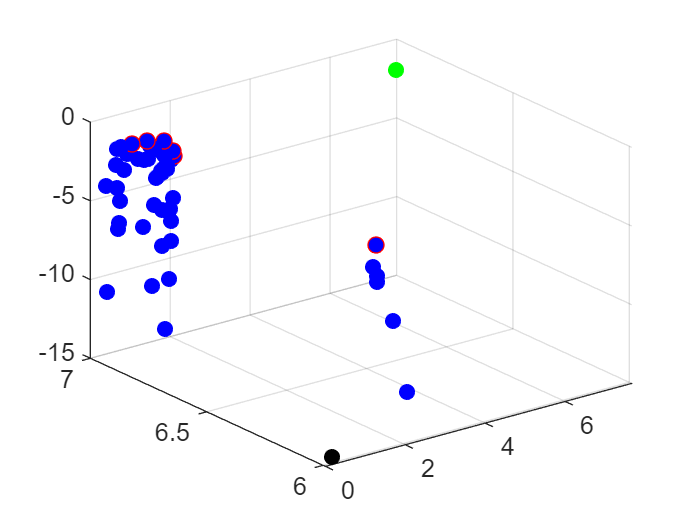

hv = 0.2484


scatter3(resultTab(:,1), resultTab(:,2), resultTab(:,3), "bo", "filled")

hold on
scatter3(paretoF(:,1), paretoF(:,2), paretoF(:,3), "ro")
scatter3(utopiaPoint(1), utopiaPoint(2), utopiaPoint(3), "go", "filled")
scatter3(antiutopiaPoint(1), antiutopiaPoint(2), antiutopiaPoint(3), "ko", "filled")
hold off

allHV = [];
for x = 7:length(resultTab(:,1))

    paretoF = paretoFront([resultTab(1:x,1) resultTab(1:x,2) resultTab(1:x,3)]);
    allHV = [allHV; hypervolume([paretoF(:,1), paretoF(:,2), paretoF(:,3)], antiutopiaPoint, utopiaPoint, 1000000)];

end

allMinHV = minResp(-allHV)

allMinHV =    -0.1483
   -0.1540
   -0.1545
   -0.1815
   -0.1815
   -0.1911
   -0.1911
   -0.2107
   -0.2116
   -0.2120


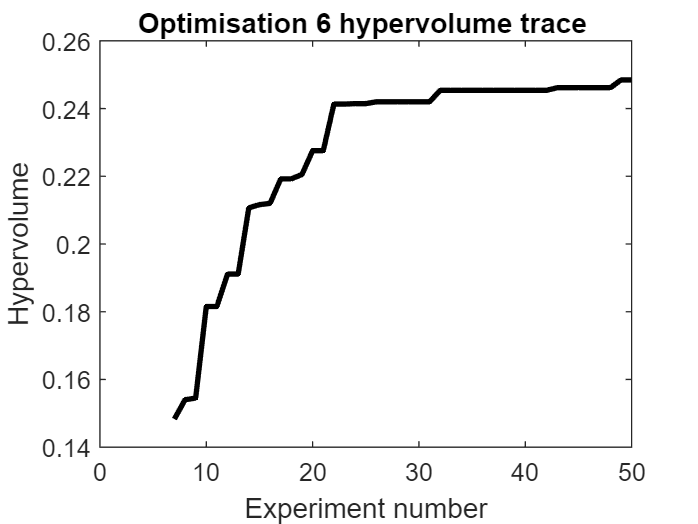


plot(7:50, -allMinHV, "black", "LineWidth", 2)

xlabel("Experiment number")
ylabel("Hypervolume")

title("Optimisation 6 hypervolume trace ")